%% 0. Initialize Parameters 
n = 1250;                  % Number of locations to evaluate bridge failure 
L = 1250;                  % Length of bridge 

%%%%%%%%%%% ALL VALUES ARE IN TERMS OF P, BUT JUST NEED TO WRITE "P" AT THE
%%%%%%%%%%% END


x = linspace(0, L, n);     % Define x coordinate 
SFD_PL = zeros(1, n);      % Initialize SFD(x) 
  
%% 1. Point Loading Analysis (SFD, BMD) 

% Calculate Forces
xP = [550, 1250];
P = [1, 1]; 
% Calculate Supports
xS = [0, 1060];
S = [0, 0];
[S(1), S(2)] = CalcSupportForces( xP, P, xS );

By = 1.6981

Ay = 0.3019

max_width = 100

max_height = 76.2700

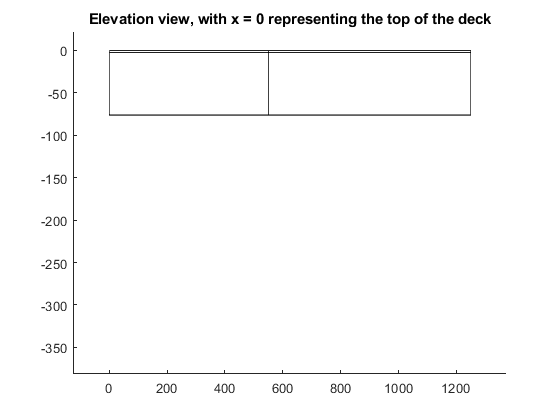

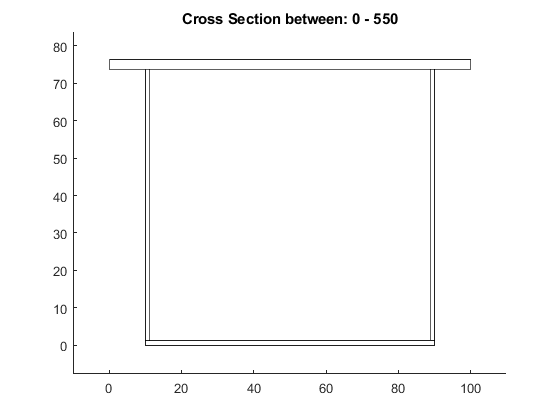

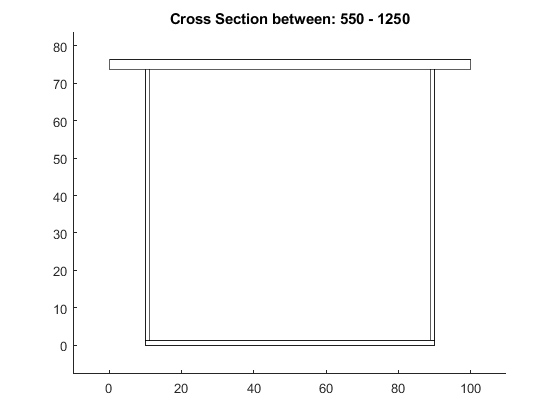


  
%% 2. Define cross-sections 
% There are many (more elegant ways) to construct cross-section objects 
xc = [0 550 L];  % Location, x, of cross-section change 
bft = [100 100 100]; % Top Flange Width 
tft = [2.54 2.54 2.54]; % Top Flange Thickness 
hw = [75-1.27*2, 75-1.27*2, 75-1.27*2];  % Web Height 
tw = [1.27 1.27 1.27]; % Web Thickness (Assuming 2 separate webs) 
spacing_web = [80 80 80]; % Includes width of the Flange
bfb = [80 80 80];  % Bottom Flange Width 
tfb = [1.27 1.27 1.27]; % Bottom Flange Thickness 
a = [0 200 400 600 800 1000 1200];   % Position of Diaphrams

% Optional but you need to ensure that your geometric inputs are correctly implemented 
VisualizeBridge( xc, bft, tft, hw, tw, spacing_web, bfb, tfb, a );  

dist_A_to_B = 1060

SFD =     0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019


SFD =     0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019


SFD =     0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019    0.3019


BMD =     0.3021    0.6043    0.9064    1.2085    1.5106    1.8128    2.1149    2.4170    2.7192    3.0213    3.3234    3.6255    3.9277    4.2298    4.5319    4.8341    5.1362    5.4383    5.7404    6.0426    6.3447    6.6468    6.9490    7.2511    7.5532    7.8553    8.1575    8.4596    8.7617    9.0639    9.3660    9.6681    9.9702   10.2724   10.5745   10.8766   11.1788   11.4809   11.7830   12.0851   12.3873   12.6894   12.9915   13.2937   13.5958   13.8979   14.2000   14.5022   14.8043   15.1064


BMD =     0.3021    0.6043    0.9064    1.2085    1.5106    1.8128    2.1149    2.4170    2.7192    3.0213    3.3234    3.6255    3.9277    4.2298    4.5319    4.8341    5.1362    5.4383    5.7404    6.0426    6.3447    6.6468    6.9490    7.2511    7.5532    7.8553    8.1575    8.4596    8.7617    9.0639    9.3660    9.6681    9.9702   10.2724   10.5745   10.8766   11.1788   11.4809   11.7830   12.0851   12.3873   12.6894   12.9915   13.2937   13.5958   13.8979   14.2000   14.5022   14.8043   15.1064


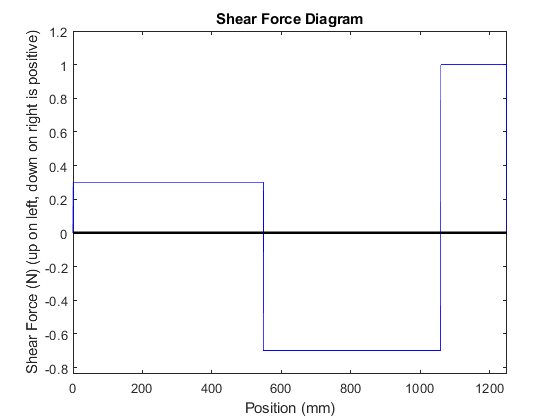

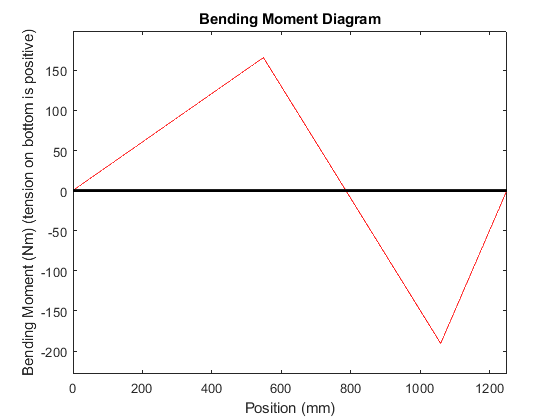

 

%[SFD_PL, BMD_PL] = ApplyPL(550, P, x, SFD_PL);      % Construct SFD, BMD 
%[SFD_PL, BMD_PL] = ApplyPL(L, P, x, SFD_PL);        % Construct SFD, BMD 
[SFD, BMD] = ApplyPL(x,xP,P,xS,S);



%% 3. Define Material Properties 
SigT = 30; 
SigC = 6; 
E    = 4000; 
TauU = 4; 
TauG = 2; 
mu   = 0.2;


  
%% 4. Calculate Failure Moments and Shear Forces 
% V_Mat = Vfail({CrossSectionInputs}, TauU); 
% V_Glue = VfailGlue({CrossSectionInputs}, TauU); 
% V_Buck = VfailBuck({CrossSectionInputs}, E, mu ); 
%   
% M_MatT = MfailMatT({CrossSectionInputs}, SigT); 
% M_MatC = MfailMatC({CrossSectionInputs}, SigC); 
% M_Buck1 = MfailBuck({CrossSectionInputs}, E, mu, 1 ); 
% M_Buck2 = MfailBuck({CrossSectionInputs}, E, mu, 2 ); 
% M_Buck3 = MfailBuck({CrossSectionInputs}, E, mu, 3 ); 
  
%% 4.7 Calculate Failure Load 
% Pf = FailLoad(P, SFD_PL, BMD_PL, V_Mat, V_Glue, V_Buck, M_MatT, M_MatC, M_Buck1, M_Buck2, M_Buck3); 
  
%% Visualization 
% VisualizePL(x, P, SFD_PL, BMD_PL, V_Mat, V_Glue, V_Buck, M_MatT, M_MatC, M_Buck1, M_Buck2, M_Buck3, Pf); 
  
%% 5. Curvature, Slope, Deflections 
% Defls = Deflections(x, BMD_PL, I, E); 
h = [1.27 1.27 1.27 75-3*1.27 75-3*1.27 1.27]; %for debugging
b = [100 10 10 1.27 1.27 80]; %for debugging 
areas = b.*h

areas =   127.0000   12.7000   12.7000   90.4113   90.4113  101.6000



distances = [(75-1.27/2) 75-1.27-(1.27/2) 75-1.27-(1.27/2) (75-1.27)/2 (75-1.27)/2 1.27/2]

distances =    74.3650   73.0950   73.0950   36.8650   36.8650    0.6350




y_bar = CalculateYBar(areas, distances)

y_bar = 41.4687

I = CalcI(b,h,y_bar, distances)

I = 4.1248e+05

[y_bar_vector, I_vector] = Calc_Cross_Section_Properties(xc, bft, tft, hw, tw, spacing_web, bfb, tfb, a)

I_vector =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y_bar_vector =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


b =   100.0000    2.5400   80.0000


h =     2.5400   72.4600    1.2700


areas =   254.0000  184.0484  101.6000


heights =    75.0000    0.6350   37.5000


b =   100.0000    2.5400   80.0000


h =     2.5400   72.4600    1.2700


areas =   254.0000  184.0484  101.6000


heights =    75.0000    0.6350   37.5000


y_bar_vector =    42.5775   42.5775   42.5775   42.5775   42.5775   42.5775   42.5775   42.5775   42.5775   42.5775   42.5775   42.5775   42.5775   42.5775   42.5775   42.5775   42.5775   42.5775   42.5775   42.5775   42.5775   42.5775   42.5775   42.5775   42.5775   42.5775   42.5775   42.5775   42.5775   42.5775   42.5775   42.5775   42.5775   42.5775   42.5775   42.5775   42.5775   42.5775   42.5775   42.5775   42.5775   42.5775   42.5775   42.5775   42.5775   42.5775   42.5775   42.5775   42.5775   42.5775


I_vector = 	1.0e+06 *

    1.6524    1.6524    1.6524    1.6524    1.6524    1.6524    1.6524    1.6524    1.6524    1.6524    1.6524    1.6524    1.6524    1.6524    1.6524    1.6524    1.6524    1.6524    1.6524    1.6524    1.6524    1.6524    1.6524    1.6524    1.6524    1.6524    1.6524    1.6524    1.6524    1.6524    1.6524    1.6524    1.6524    1.6524    1.6524    1.6524    1.6524    1.6524    1.6524    1.6524    1.6524    1.6524    1.6524    1.6524    1.6524    1.6524    1.6524    1.6524    1.6524    1.6524


function [ y_bar ] = CalculateYBar (areas, distances)
    y_bar = sum((areas .* distances)) / sum(areas);
end

function [ I ] = CalcI(b,h,y_bar, dists_from_centroid) %b, h, dist_from_centroid are all vectors
    I = sum(b.*h.^3/12) + sum(b.*h.*(dists_from_centroid-y_bar).^2); %assuming all of the components are rectangles 
end 

%%%%%%%%%%%%%%%%%ADD CALCULATION FOR DIAPHRAMS
function [ y_bar_vector, I_vector ] = Calc_Cross_Section_Properties(xc, bft, tft, hw, tw, spacing_web, bfb, tfb, a)
%     xc = [0 550 L];  % Location, x, of cross-section change 
%     bft = [100 100 100]; % Top Flange Width 
%     tft = [2.54 2.54 2.54]; % Top Flange Thickness 
%     hw = [100 120 100];  % Web Height 
%     tw = [1.27 1.27 1.27]; % Web Thickness (Assuming 2 separate webs) 
%     spacing_web = [80 80 80]; % Includes width of the Flange
%     bfb = [80 80 80];  % Bottom Flange Width 
%     tfb = [1.27 1.27 1.27]; % Bottom Flange Thickness 
%     a = [400 400 400];   % Diaphragm Spacing 
    I_vector = zeros(1,xc(end))
    y_bar_vector = zeros(1,xc(end))
    for interval = 1:length(xc) - 1
        % Assume Flaps used for gluing are not significant
        %    Base of top,   total base of web, base of bot
        b = [bft(interval), 2*tw(interval), bfb(interval)]
        h = [tft(interval), hw(interval), tfb(interval)]
        areas = b.*h
        heights = [hw(interval)+tfb(interval)+tft(interval)/2, tfb(interval)/2, tfb(interval)+hw(interval)/2]
        for x_value = xc(interval)+1:xc(interval + 1)
            y_bar_vector(x_value) = CalculateYBar( areas, heights);
            I_vector(x_value) = CalcI(b, h, y_bar_vector(x_value), heights - y_bar_vector(x_value));
        end
    end
    
end

function [ Ay, By ] = CalcSupportForces( xP, P, xS )
    % Calculate the support forces in "N"s
    By = sum((xP-xS(1)).*P) / xS(2) - xS(1)
    %By = sum((xP - dist_A_to_B).*P) % Clockwise Positive
    Ay = sum(P)-By
end

function [ BMD ] = CalculateBMD(SFD, x)
    BMD = cumsum(SFD)*((x(2)-x(1))/1) % Convert to mm
end

function [ SFD, BMD ] = ApplyPL( x, xP, P, xS, S )
    dist_A_to_B = xS(2) - xS(1)
    SFD = S(1)*ones(1,1250)
    SFD(xP:end) = SFD(xP:end)-P(1)
    SFD(dist_A_to_B:end) = SFD(dist_A_to_B:end) + S(2)

    %want to plot BMD and SFD 
    BMD = CalculateBMD(SFD, x)
    %BMD(xP) = BMD(1)-SFD(xP).*xP
    %BMD(dist_A_to_B) = BMD(xP)-SFD(xP).*(dist_A_to_B-xP(i))
    
    % PLOT SFD
    SFD(1) = 0; % Just to make the graph pretty
    SFD(end) = 0;
    plot(x,SFD, "b")
    hold on
    plot(x, zeros(1, length(x)), "k", "lineWidth", 2)
    axis([0, 1250, min(SFD) * 1.2, max(SFD) * 1.2])
    title("Shear Force Diagram")
    ylabel("Shear Force (N) (up on left, down on right is positive)")
    xlabel("Position (mm)")
    hold off    
    
    % PLOT BMD
    figure
    plot(x,BMD,"r")
    hold on
    plot(x, zeros(1, length(x)), "k", "lineWidth", 2)
    axis([0, 1250, min(BMD) * 1.2, max(BMD) * 1.2])
    title("Bending Moment Diagram")
    ylabel("Bending Moment (Nm) (tension on bottom is positive)")
    xlabel("Position (mm)")
    hold off
end 


% Constructs SFD and BMD from application of 1 Point Load. Assumes fixed location of supports 
% Input: location and magnitude of point load. The previous SFD can be entered as input to  
%  construct SFD of multiple point loads 

% Output: SFD, BMD both 1-D arrays of length n 


function [  ] = VisualizeBridge( xc, bft, tft, hw, tw, spacing_web, bfb, tfb, a ) 
% Optional. Provides a graphical interpretation of user geometric inputs 
    
    % Assuming that the maximum width of the beam will be either the top or
    % bottom flange:
    max_width = max(max(bft), max(bfb))
    max_height = max(tft + tfb + hw)

    %% Draw out the Elevation View
    figure
    for i = 1:length(xc) -1
        rectangle('Position', [xc(i), -tft(i), xc(i+1) - xc(i),  tft(i)]) % Draw the Top Flange
        rectangle('Position', [xc(i), -tft(i)-hw(i), xc(i+1) - xc(i),  hw(i)]) % Draw the Web
        rectangle('Position', [xc(i), -tft(i)-hw(i)-tfb(i), xc(i+1) - xc(i),  tfb(i)]) % Draw the Bottom Flange
    end
    axis([(xc(end) - xc(1)) * (-0.1), (xc(end) - xc(1)) * 1.1, max_height * (-5), max_height * 0.3])
    title("Elevation view, with x = 0 representing the top of the deck")

    %% Draw out the cross-section in each interval    
    for i = 1:length(xc) -1
        figure
        rectangle('Position', [0, hw(i)+tfb(i), bft(i),  tft(i)]) % Draw the Top Flange
        rectangle('Position', [(bft(i) - bfb(i)) / 2, 0, bfb(i),  tfb(i)]) % Draw the Bottom Flange
        rectangle('Position', [((max_width / 2) - (spacing_web(i) / 2)), tfb(i), tw(i), hw(i)]) % Draw the Left-Side of the Web
        rectangle('Position', [((max_width / 2) + (spacing_web(i) / 2))- tw(i), tfb(i), tw(i), hw(i)]) % Draw the Right-Side of the Web
        
        axis([max_width * (-0.1), max_width * 1.1, max_height * (-0.1), max_height * 1.1])
        title("Cross Section between: " + xc(i) + " - " + xc(i+1))
    end
end



%  function [ {Sectional Properties} ] = SectionProperties( {Geometric Inputs} ) % Calculates important sectional properties. Including but not limited to ybar, I, Q, etc. 
% % Input: Geometric Inputs. Format will depend on user 
% % Output: Sectional Properties at every value of x. Each property is a 1-D array of length n 
%  
% function [ V_fail ] = Vfail( {Sectional Properties}, TauU ) 
% % Calculates shear forces at every value of x that would cause a matboard shear failure 
% % Input: Sectional Properties (list of 1-D arrays), TauU (scalar material property) 
% % Output: V_fail a 1-D array of length n 
%     I = {Sectional Properties}; 
%     b = {Sectional Properties}; 

function [Qcent] = CalcQcent(top_areas, local_centroidal_heights) %calculating from the top , calculate local_centroidal_heights of the top half of the structure beforehand 
    Qcent = sum(areas.*((local_centroidal_heights)))
end
%  function [ {Sectional Properties} ] = SectionProperties( {Geometric Inputs} ) % Calculates important sectional properties. Including but not limited to ybar, I, Q, etc. 
% % Input: Geometric Inputs. Format will depend on user 
% % Output: Sectional Properties at every value of x. Each property is a 1-D array of length n 
%  
function [ V_fail ] = CalcVfail( Qcent, I, b, TauU ) 
% % Calculates shear forces at every value of x that would cause a matboard shear failure 
% % Input: Sectional Properties (list of 1-D arrays), TauU (scalar material property) 
% % Output: V_fail a 1-D array of length n 
     V_fail = TauU .* I .* b ./ Qcent;  %give out result in newtons 
end 

function [ybot, ytop] = CalcYbotYtop(height, y_bar)
    ybot = y_bar
    ytop = height - y_bar
end



function [ M_MatT ] = MfailMatT( ybot, ytop, I, SigT, BMD )  
% % Calculates bending moments at every value of x that would cause a matboard tension failure 
% % Input: Sectional Properties (list of 1-D arrays), SigT (material property), BMD (1-D array) 
% % Output: M_MatT a 1-D array of length n 
    M_MatT = zeros(1,1250)
    for i = 1 : length(x)    
            if BMD(i) > 0 % If the moment is positive, the tension failure will be at the bottom 
                M_MatT(i) = SigT * I(i) / ybot(i); 
            elseif BMD(i) < 0 % If the moment is negative, the tension failure will be at the top 
                M_MatT(i) = -SigT * I(i) / ytop(i); 
            end 
    end 

end 

function [ P_fail ] = MfailMatC(ybot, ytop, I, Stress_fail, BMD) % Similar to MfailMatT 
      M_fail = zeros(1,1250)
      
      for i = 1 : length(x)    
            if BMD(i) > 0 % If the moment is positive, the tension failure will be at the bottom 
                M_fail(i) = Stress_fail * I(i) / ytop(i); 
            elseif BMD(i) < 0 % If the moment is negative, the tension failure will be at the top 
                M_fail(i) = -Stress_fail * I(i) / ybot(i); 
            end 
      end 
      
      P_fail = M_fail ./ BMD

end
%  function [ M_Buck ] = MfailBuck( {Sectional Properties}, E, mu, BMD )  
% % Calculates bending moments at every value of x that would cause a buckling failure 
% % Input: Sectional Properties (list of 1-D arrays), E, mu (material property), BMD (1-D array) 
% % Output: M_MatBuck a 1-D array of length n 
%  function [ Pf ] = FailLoad( P, SFD, BMD, V_Mat, V_Buck, M_MatT, M_MatC, M_Buck1, M_Buck2, M_Buck3 )  
% % Calculates the magnitude of the load P that will cause one of the failure mechanisms to occur 
% % Input: SFD, BMD under the currently applied points loads (P) (each 1-D array of length n) 
% %  {V_Mat, V_Glue, ... M_MatT, M_MatC, ... } (each 1-D array of length n) 
% % Output: Failure Load value Pf 
%  function [] = VisualizePL(x, SFD, BMD, V_Mat, V_Buck, M_MatT, M_MatC, M_Buck1, M_Buck2,..., Pf)  
% % Plots all outputs of design process 
%  function [ Defls ] = Deflections( x, BMD, I, E )  
% % Calculates deflections 
% % Input: I(1-D arrays), E (material property), BMD (1-D array) 
% % Output: Deflection for every value of x (1-D array) or for the midspan only  




